# The relationship between accuracy and RTs in color naming and color categorization

addpath('/Users/ksiuda/Dropbox (PICNIC Lab)/Kasia/Colors/color_connectivity/behavioral_corelates')
load('RDS_CTRL_18.mat')

subjects = [1 2 3 6 8:23 ];
subjects = subjects+1;
T(T.Sujet_Number==1, :)=[];
T(~ismember(subjects, T.Sujet_Number), :)=[];
T(~ismember(T.Sujet_Number, subjects), :)=[];

T(T.No_Bloc==1 | T.No_Bloc==3, :)=[];



Compute and compare subject-wise variance for ACC and RT in CC and CN

[subject_task_id, subject, task] = findgroups(T.Sujet_Number, T.Task_Type);
RT = splitapply(@mean, T.RT, subject_task_id)

RT =     2.1099
    1.0233
    2.3682
    1.0912
    1.1683
    0.9979
    2.2119
    1.1721
    1.7935
    1.1796


ACC = splitapply(@mean, T.Accuracy,  subject_task_id)

ACC =     0.8344
    1.0000
    0.8662
    1.0000
    0.8917
    0.9936
    0.8408
    0.9936
    0.8981
    0.9904


ans =     0.7532    1.6828
    1.0000    1.9547
    1.0000    2.1037
    0.8766    1.8963
    0.8347    2.1037
    0.8963    2.0000
    1.0704    2.1359
    1.2111    1.7734
    0.9296    1.8641
    1.0000    2.0000


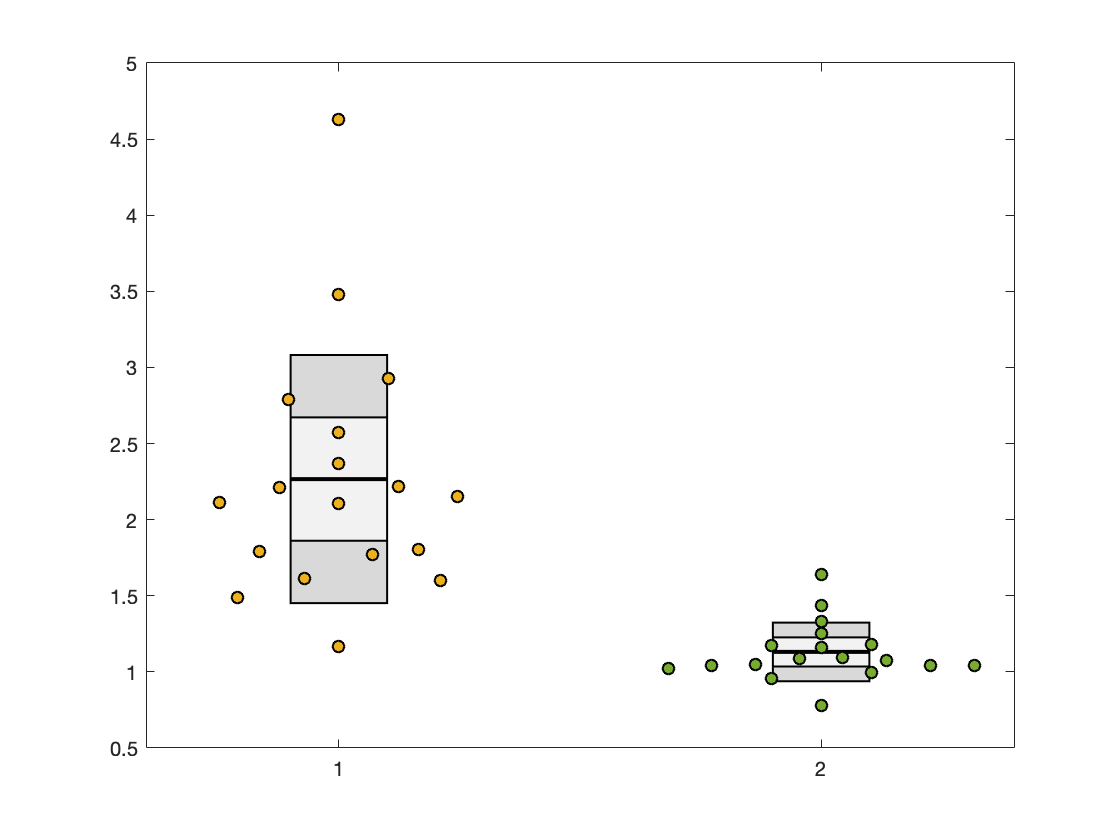

T2 = table(subject, task, RT, ACC);

UnivarScatter([T2.RT(strcmp(T2.task, 'CC')),T2.RT(strcmp(T2.task, 'CN'))])

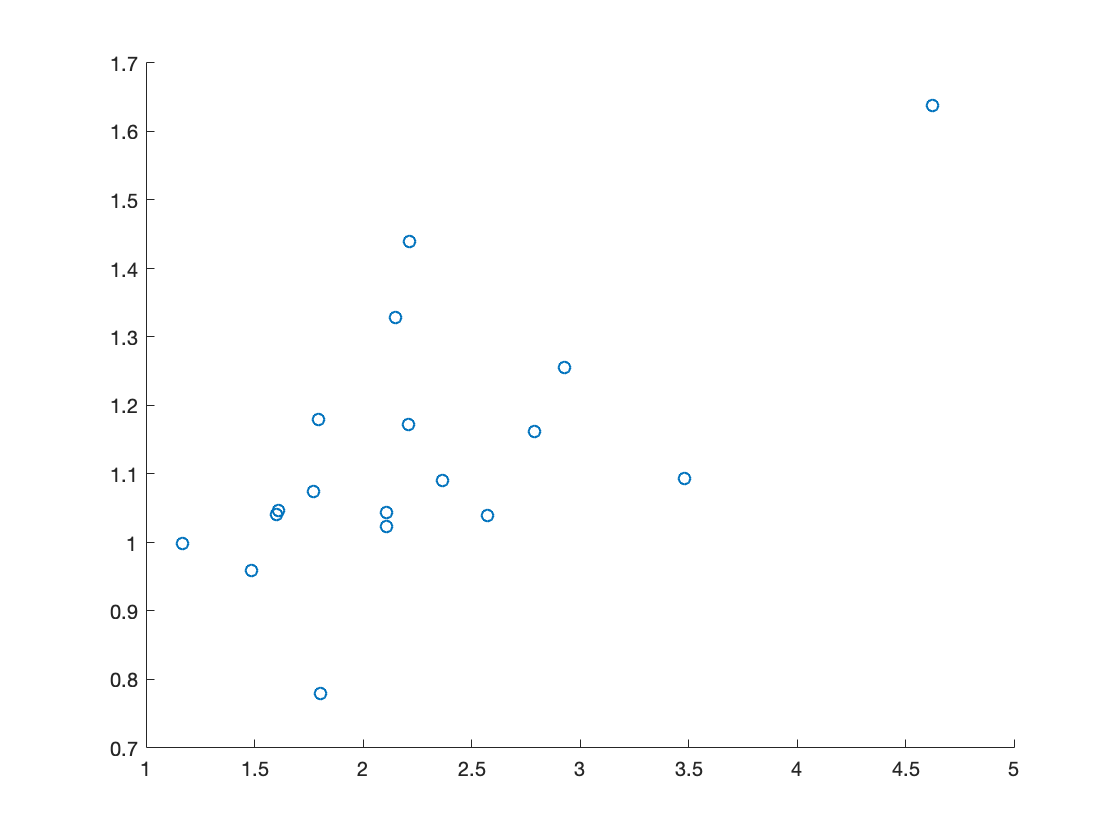

%do naming and categorization correlate?

scatter(T2.RT(strcmp(T2.task, 'CC')),T2.RT(strcmp(T2.task, 'CN')))

ans =     0.8347    1.8347
    1.0000    2.1653
    1.0000    2.2266
    1.1653    1.8641
    0.7246    1.6828
    1.0000    2.0000
    1.2754    1.7889
    1.0000    2.0000
    1.0000    2.1359
    0.8963    2.3172


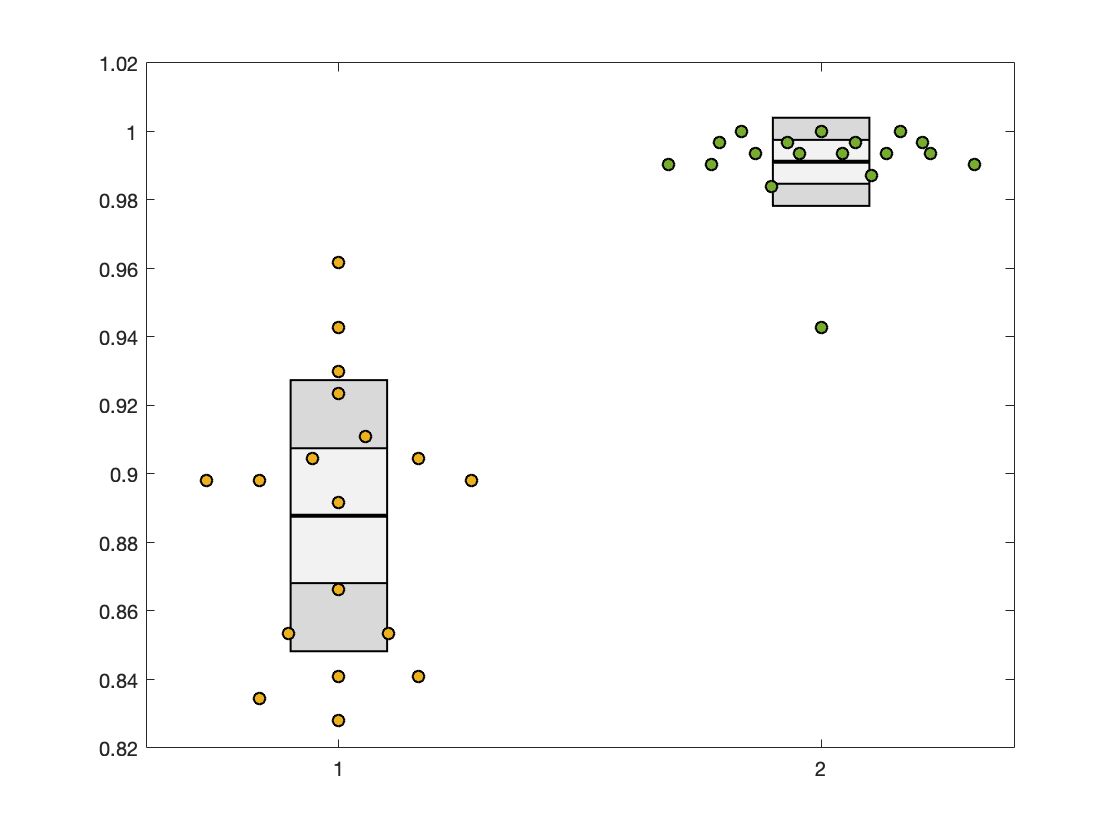

[h,p,ci,stats] = vartest2(T2.RT(strcmp(T2.task, 'CC')),T2.RT(strcmp(T2.task, 'CN')))

UnivarScatter([T2.ACC(strcmp(T2.task, 'CC')),T2.ACC(strcmp(T2.task, 'CN'))])

vartest2(T2.ACC(strcmp(T2.task, 'CC')),T2.ACC(strcmp(T2.task, 'CN')))

ans = 1

[h,p,ci,stats] = vartest2(T2.RT(strcmp(T2.task, 'CN')),T2.ACC(strcmp(T2.task, 'CN')))

h = 1

p = 2.4516e-16

ci =    83.8341
  599.1233


stats = struct with fields:
    fstat: 224.1137
      df1: 17
      df2: 17


var(T2.RT(strcmp(T2.task, 'CN')))

ans = 0.0371

var(T2.ACC(strcmp(T2.task, 'CN')))

ans = 1.6533e-04